clear; close all; clc;
addpath('/Users/Jameskyle/Desktop/CMU/24-775 Bioinspired Robot Design and Experimentation/AcroBOT/RDA Functions');

# AcroBOT EOM Derivation

### Initializing variables and parameters:

% States
syms theta_1 theta_2 theta_3...
     theta_dot_1 theta_dot_2 theta_dot_3...
     theta_ddot_1 theta_ddot_2 theta_ddot_3...
     m_l1 m_l2 m_l3 l1 l2 l3 c1 c2 c3 real

% Paramters
% m_l1 = 1;
% m_l2  = 1;
% m_l3  = 1;
g = 9.81;
% l1 = 1;
% l2 = 1;
% l3 = 1;
I_l1 = 1/12*m_l1*l1^2;
I_l2 = 1/12*m_l2*l2^2;
I_l3 = 1/12*m_l3*l3^2;
params = [m_l1 m_l2 m_l3 l1 l2 l3 c1 c2 c3]';

% Inputs
syms tau_1 tau_2 tau_3 real
inputs = [tau_1;tau_2;tau_3];

% Local coordinates
q = [theta_1;theta_2;theta_3];
dq = [theta_dot_1;theta_dot_2;theta_dot_3];
ddq = [theta_ddot_1;theta_ddot_2;theta_ddot_3];


### Generating dynamics:

% TODO: Compute inertia matrix in local coordinates M
% Transformation for Frame 1
g_s1 = [ cos(theta_1)  -sin(theta_1)  0  0 ;
         sin(theta_1)   cos(theta_1)  0  0 ;
              0              0        1  0 ;
              0              0        0  1 ];
g_1L1 = [ 1  0  0   c1 ;
          0  1  0   0  ;
          0  0  1   0  ;
          0  0  0   1  ];
g_sL1 = g_s1*g_1L1;


% Transformation for Frame 2
g_L12 = [ cos(theta_2)  -sin(theta_2)  0  l1-c1 ;
          sin(theta_2)   cos(theta_2)  0    0  ;
               0              0        1    0  ;
               0              0        0    1  ];
g_2L2 = [ 1  0  0   c2 ;
          0  1  0   0  ;
          0  0  1   0  ;
          0  0  0   1  ];
g_sL2 = simplify(g_sL1*g_L12*g_2L2);


% Transformation for Frame 3
g_L23 = [ cos(theta_3)  -sin(theta_3)  0  l2-c2 ;
          sin(theta_3)   cos(theta_3)  0    0  ;
               0              0        1    0  ;
               0              0        0    1  ];
g_3L3 = [ 1  0  0   c3 ;
          0  1  0   0  ;
          0  0  1   0  ;
          0  0  0   1  ];
g_sL3 = simplify(g_sL2*g_L23*g_3L3);


% Jacobians for each frame
J1 = diff(g_sL1,q(1))/g_sL1;
J2 = diff(g_sL1,q(2))/g_sL1;
J3 = diff(g_sL1,q(3))/g_sL1;
Js_sL1 = [rbvel2twist(J1) rbvel2twist(J2) rbvel2twist(J3)];
Jb_sL1 = tform2adjoint(g_sL1)\Js_sL1;

J1 = diff(g_sL2,q(1))/g_sL2;
J2 = diff(g_sL2,q(2))/g_sL2;
J3 = diff(g_sL2,q(3))/g_sL2;
Js_sL2 = [rbvel2twist(J1) rbvel2twist(J2) rbvel2twist(J3)];
Jb_sL2 = tform2adjoint(g_sL2)\Js_sL2;

J1 = diff(g_sL3,q(1))/g_sL3;
J2 = diff(g_sL3,q(2))/g_sL3;
J3 = diff(g_sL3,q(3))/g_sL3;
Js_sL3 = [rbvel2twist(J1) rbvel2twist(J2) rbvel2twist(J3)];
Jb_sL3 = tform2adjoint(g_sL3)\Js_sL3;


% Inertia Tensor
I_l1_matrix = [zeros(3,2) [0 0 1]'.*I_l1];
I_l2_matrix = [zeros(3,2) [0 0 1]'.*I_l2];
I_l3_matrix = [zeros(3,2) [0 0 1]'.*I_l3];


Mo_1 = [ m_l1.*eye(3)  zeros(3,3) ;
          zeros(3,3)   I_l1_matrix  ];
Mo_2 = [ m_l2.*eye(3)  zeros(3,3) ;
          zeros(3,3)   I_l2_matrix  ];
Mo_3 = [ m_l3.*eye(3)  zeros(3,3) ;
          zeros(3,3)   I_l3_matrix  ];

M = simplify(expand(Jb_sL1'*Mo_1*Jb_sL1 + Jb_sL2'*Mo_2*Jb_sL2 + Jb_sL3'*Mo_3*Jb_sL3));

% TODO: Compute Coriolis matrix in local coordinates C
C = coriolisMatrix(M,q,dq);

% TODO: Compute nonlinear terms N
% beta = diag([beta_1 beta_2]);
V = m_l1*g*g_sL1(2,end) + m_l2*g*g_sL2(2,end) + m_l3*g*g_sL3(2,end);
N = jacobian(V,q)'; % + beta*dq;

% TODO: Compute applied force Y
Y = inputs;



## Generate EOM Function:

functionName = 'AcroBOTDynamics';
genNewFuction = 0;

if genNewFuction
    matlabFunction(M, C, N, Y,'var',{q,dq,inputs,params},'FILE',functionName)
end

ans = function_handle with value:
    @AcroBOTDynamics


## Simulate System for Sanity Check:

ts = 0;
tf = 10;
dt = 0.01;
tspan = ts:dt:tf;

q0 = [0;0;0];
dq0 = [0;0;0];
x0 = [q0;dq0];

gymnastSYS.m = [1;1;1];
gymnastSYS.l = [1;1;1];
gymnastSYS.c = [0.9;0.9;0.9];

options = odeset('MaxStep',0.01);
[t, x] = ode45(@(t,x) triplePendulumSim(t,x,gymnastSYS),tspan,x0,options);



### Plotting Results:

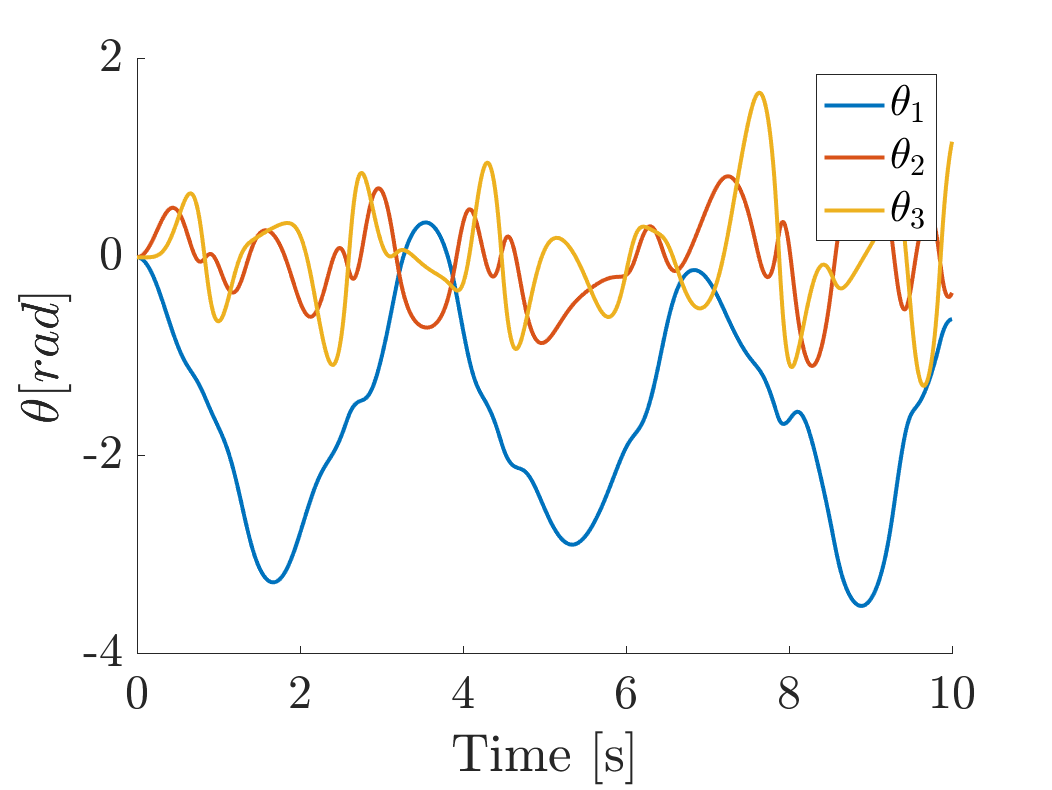

th1 = x(:,1);
th2 = x(:,2);
th3 = x(:,3);
figure();
hold on
plot(t,th1,'linewidth',2,'DisplayName','$\theta_1$');
plot(t,th2,'linewidth',2,'DisplayName','$\theta_2$');
plot(t,th3,'linewidth',2,'DisplayName','$\theta_3$');
hold off
ylabel('$\theta [rad]$');
xlabel('Time [s]');
legend('Interpreter','Latex');

function dx = triplePendulumSim(t,x,SYS)

q = x(1:3);
dq = x(4:6);

params = [SYS.m; SYS.l; SYS.c];

inputs = zeros(3,1);

[M, C, N, Y] = AcroBOTDynamics(q,dq,inputs,params);


ddq = M\(Y - C*dq - N);

dx = [dq;ddq];

end
